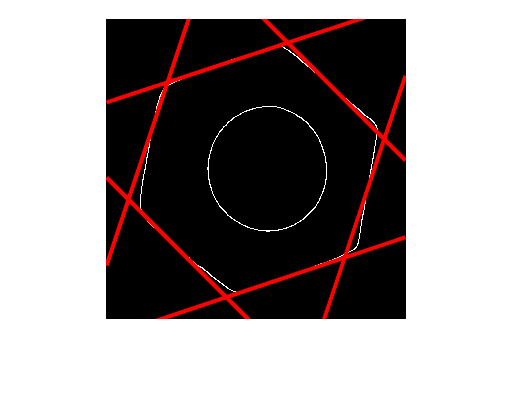

%%% 1.b

clc
clear

img = imread('HW2.jpg'); 
img_gray = rgb2gray(img); 
img_BW = imbinarize(img_gray); 
img_BW = imcomplement(img_BW); 
img_edge = edge(img_BW, 'canny');
B = bwboundaries(img_edge,'noholes');
B = B{1}; 

[rows, columns] = size(img_BW);
[gy, gx] = imgradientxy(img_edge);
A= zeros(800,800);

for i=1:size(B,1)
        y=B(i,1);
        x=B(i,2);

        if gx(x,y)~=0 && gy(x,y)~=0
            v=(x*gx(x,y)+y*gy(x,y))./(gx(x,y)^2 + gy(x,y)^2);
            x0=round(v*gx(x,y));
            y0=round(v*gy(x,y));
            A(x0+100,y0+100)=A(x0+100,y0+100)+1;
        end
        

end

figure;
imshow(img_edge);
hold on;

peak = houghpeaks(A,8,"Threshold",1);

peak(7,:)=[];
peak(6,:)=[];
for i=1:6

    pointx0=peak(i,1) - 100;
    pointy0=peak(i,2) - 100;

    slope=-pointx0/pointy0;
    b=pointy0-pointx0.*slope;
    xx = 1:300;
    yy=xx.*slope + b;

    plot(xx,yy, 'Color', 'r', 'LineWidth', 2);

end

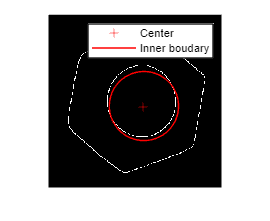

%%% 1.c

clear;
close all
image=imread('HW2.jpg');
image_bw=rgb2gray(image);
img_BW = imbinarize(image_bw); 
img_BW = imcomplement(img_BW); 
edge=edge(img_BW,'canny');

[Gx,Gy]=imgradientxy(edge);

B = bwboundaries(edge,'holes');
B = B{2}; 



R=1:1:70;
A2=zeros(size(edge,1),size(edge,2),size(R,2));
[Gy,Gx]=imgradientxy(edge);

c=0;
for k=1:size(R,2)
    for i=1:size(B,1)
           x=B(i,2);
           y=B(i,1);
           if Gx(x,y)~=0 && Gy(x,y)~=0
                xc=round(x-R(k)*Gx(x,y)/sqrt(Gx(x,y)^2+Gy(x,y)^2)); % Determination of x_center of the circle using Hough Transform for a circle
                yc=round(y-R(k)*Gy(x,y)/sqrt(Gx(x,y)^2+Gy(x,y)^2)); % Determination of y_center of the circle using Hough Transform for a circle
                if xc>0 && xc<=size(edge,1) && yc>0 && yc<=size(edge,2) % We only keep the (xc,yc) which are on the image.
                    A2(xc,yc,k)=A2(xc,yc,k)+1; % Accumulated matrix 
                    
                end
           end

    end
end

peak = houghpeaks(A2(:,:,1),1);
x_centroid = peak(1,1)+50;
y_centroid = peak(1,2)+50;
R_centroid = 60;
angle=0:0.01:2*pi;
x_circle=x_centroid-R_centroid*cos(angle); % (rho,theta) => (x,y)
y_circle=y_centroid-R_centroid*sin(angle); % (rho,theta) => (x,y)

figure(3) % Plot of the circle fund previously with Hough Transform.
imshow(edge);
hold on
plot(x_centroid,y_centroid,'r+');
plot(x_circle,y_circle,'r');
legend('Center','Inner boudary')

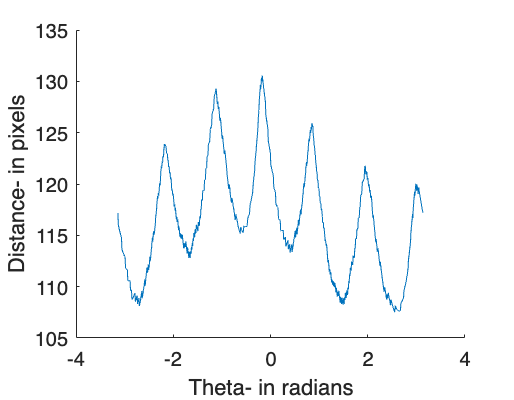


%%% 2.a


% https://github.com/CaiSean/Machine-Vision-ME6406/tree/master/Hough-Transform%20Example%20Code
clc
clear
clf

im= imread('HW2.jpg');
im= rgb2gray(im);
img_BW = imbinarize(im); 
img_BW = imcomplement(img_BW); 
im = edge(img_BW);


B = bwboundaries(im,'holes');
B = B{1}; 
xall=B(:,1);
yall=B(:,2);
[row,col]=size(im);
A=zeros(row,col);
s = regionprops(im,'Area', 'centroid');
centroids = cat(1, s.Centroid);

reference= centroids;
yc=reference(1,1);
xc=reference(1,2);
hold on
r=[];
t=[];
X=[];
Y=[];


for i=1:size(B,1)
           x=B(i,2);
           y=B(i,1);
          

          rho = ((x-xc).^2 + (y-yc).^2).^0.5;
          theta= atan2((y-yc),(x-xc));
          t = [t theta];
          r=[r rho];

         
    
end
t = sort(t);

plot(t,r);
xlabel('Theta- in radians');
ylabel('Distance- in pixels');
hold off

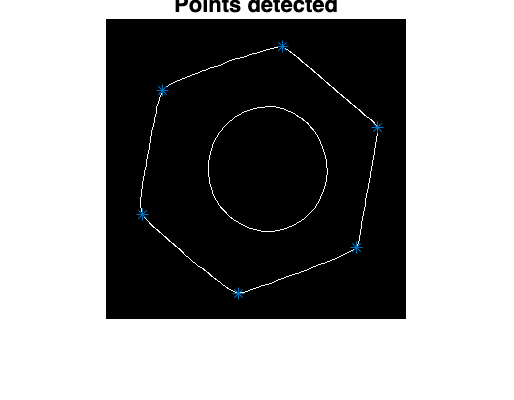


[peaks,locs]= findpeaks(r,'MinPeakDistance',80);

figure 
imshow(im)
hold on
plot( yall(locs),xall(locs),'*');
title('Points detected')
hold off

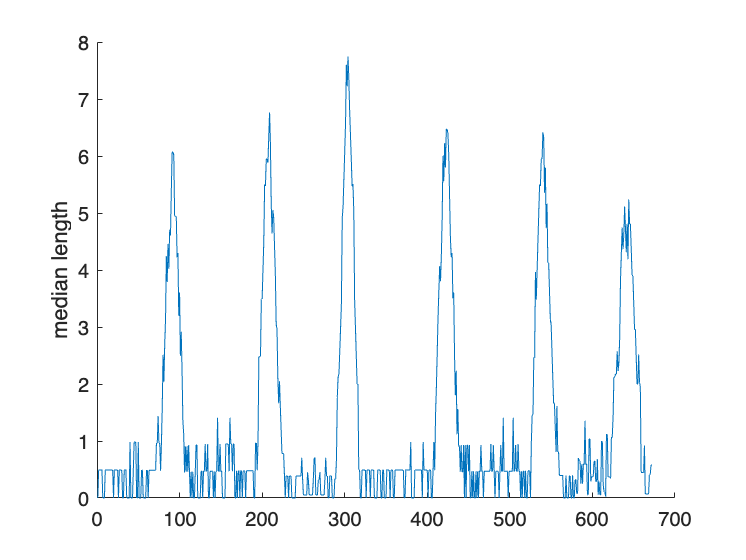

%%% 2.b

im= imread('HW2.jpg');
im= rgb2gray(im);

bwImg=im2bw(im,0.2);
bwImg=imcomplement(bwImg);

[B,L,N,A]= bwboundaries(bwImg);
xall=B{1}(:,1);
yall=B{1}(:,2);
X=[xall;xall]';
Y=[yall;yall]';
n=15;
D=[];
clf
hold on
for i=1:(size(X,2)/2)
    X0=X(i+n);
    X1=X(i);
    X2=X(i+2*n);
    Y0=Y(i+n);
    Y1=Y(i);
    Y2=Y(i+2*n);
     d= abs(((Y2-Y1)*X0 - (X2-X1)*Y0 +X2*Y1- Y2*X1)/((Y2-Y1)^2+(X2-X1)^2)^0.5);
    D=[D d];
end
clf

hold on
plot(1:size(X,2)/2,D);
ylabel('median length')
hold off

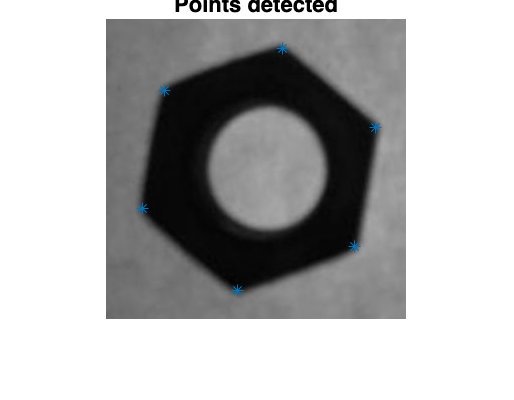


[peaks,locs]= findpeaks(D,'MinPeakDistance',60);
locs(1)=[];
locs= locs+n;
figure 
imshow(im)
hold on
plot( yall(locs),xall(locs),'*');
title('Points detected')
hold off

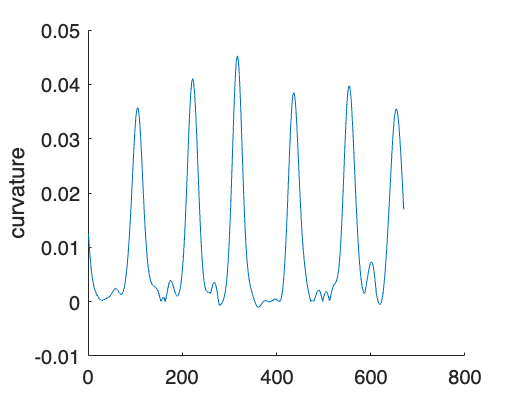

%%% 2.c

im= imread('HW2.jpg');
im= rgb2gray(im);
bwImg= im2bw(im,0.2);
bwImg= imcomplement(bwImg);
[B,L,N,A]= bwboundaries(bwImg,'noholes');
x=B{1}(:,2);
y=B{1}(:,1);
x=[x;x];
y=[y;y];
n=length(x);
s=linspace(-n/2,n/2,n);
sigma=10;
g0=1/sqrt(2*pi*sigma^2)*exp(-s.^2/(2*sigma^2));
g=[g0 g0]';
X=conv(x,g,'same');
X=X(1:round(end/2));
Y=conv(y,g,'same');
Y=Y(1:round(end/2));
Xd=diff(X);
Xdd=diff(Xd);
Yd=diff(Y);
Ydd=diff(Yd);
X_vec=[];
Y_vec=[];
for i=1:length(Xdd)
    X_vec=[X_vec X];
    Y_vec=[Y_vec Y];
    K(i)=abs(Xd(i)*Ydd(i))-(Xdd(i)*Yd(i));
end

clf

hold on
plot(1:length(K(1:end)),K(1:end));
ylabel('curvature');
hold off

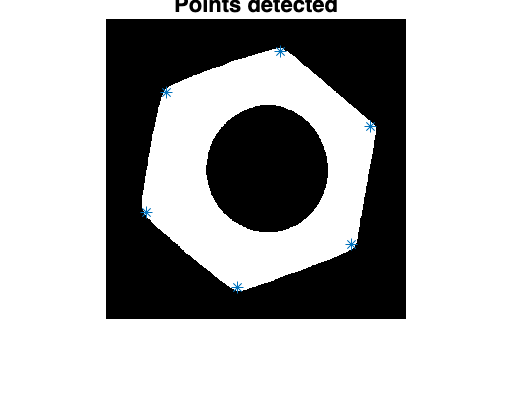

[peaks,locs]= findpeaks(K,'MinPeakDistance',80);
% locs(1)=[];
% locs(7)=[];
% locs(6)=[];
figure 
imshow(bwImg)
hold on
plot( X_vec(locs),Y_vec(locs),'*');
title('Points detected')
hold off

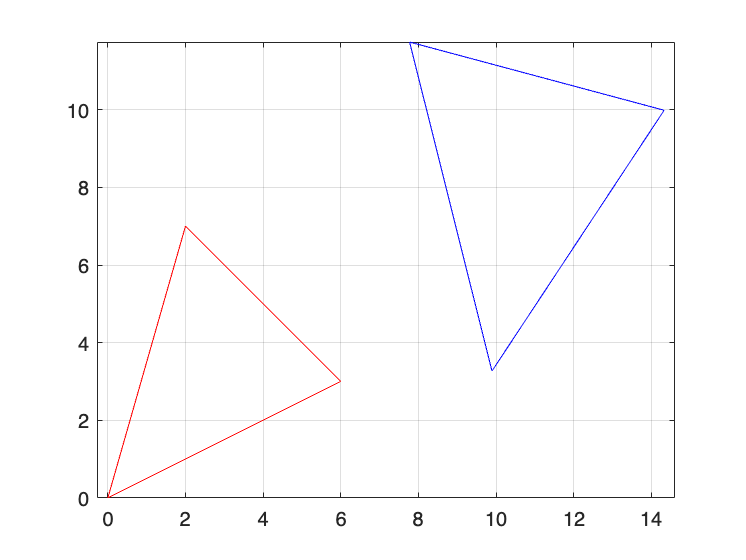

%%% 3.a

clear
clc

k=1.2;
theta=30;
theta_r= pi/6;
Xd=8;
Yd=5;

X0=[0 6 2];
Y0=[0 3 7];
Xc=(X0(1)+X0(2)+X0(3))/3;
Yc=(Y0(1)+Y0(2)+Y0(3))/3;
X = X0-Xc;
Y=Y0-Yc;


q1=k.*cos(theta_r);
q2=k.*sin(theta_r);
q3=Xc+Xd;
q4=Yc+Yd;
Q=[q1;q2;q3;q4];
R=[];

A=[X(1) -Y(1) 1 0;Y(1) X(1) 0 1;
   X(2) -Y(2) 1 0;Y(2) X(2) 0 1;
   X(3) -Y(3) 1 0;Y(3) X(3) 0 1];


R1 = A*Q;


cols=length(R1)/2;
R=reshape(R1,[2,cols]);
x1 = R(1,:);
y1 = R(2,:);
clf
plot([x1,R(1,1)], [y1,R(2,1)], 'b-'); 
grid on
hold on
% 'b-' specifies a blue line
plot([X0,X0(1)], [Y0,Y0(1)], 'r-');
hold off;
axis equal;

%%% 3.b

Qt = (A'*A)^-1 *A'*R1;
kd_ = sqrt(Qt(1)^2 + Qt(2)^2)

kd_ = 1.2000

theta_ = atan(Qt(2)/Qt(1))

theta_ = 0.5236

xd_ = Qt(3)-Xc

xd_ = 8

yd_ = Qt(4)-Yc

yd_ = 5

%%% 3.c

clear 
clc

X=[2 5 5 4 1];
Y=[1 2 4 5 3];
pointst = [9.697 6.96; 8.566 8.091; 6.869 5.263];

points = [2 1; 5 2; 5 4; 4 5; 1 3];

xt=[9.697 8.566 6.869];
yt=[6.96 8.091 5.263];

% Determine the number of points
numPoints = size(points, 1);

% Define the number of points in each triangle (3 for triangles)
numPointsInTriangle = 3;

% Initialize a matrix to store all possible combinations of points
combinations = nchoosek(1:numPoints, numPointsInTriangle);
Et = inf;
Et1 = inf;
temp = [];
% Iterate through all combinations and form triangles
for i = 1:size(combinations, 1)
    E=0;
    % Get the indices of the points for the current combination
    triangleIndices = combinations(i, :);
    
    % Extract the coordinates of the points for the current triangle
    trianglePoints = points(triangleIndices, :);
    temp = [temp trianglePoints];
    %[xc, yc] = centroid(trianglePoints);
    xc = mean(trianglePoints(:,1));
    yc = mean(trianglePoints(:,2));
    A=[pointst(1,1)-xc -pointst(1,2)-yc 1 0; pointst(1,2)-yc  pointst(1,1)-xc 0 1;
       pointst(2,1)-xc -pointst(2,2)-yc 1 0; pointst(2,2)-yc  pointst(2,1)-xc 0 1;
       pointst(3,1)-xc -pointst(3,2)-yc 1 0; pointst(3,2)-yc  pointst(3,1)-xc 0 1];
    
    R = [trianglePoints(1,1); trianglePoints(1,2);
         trianglePoints(2,1); trianglePoints(2,2);
         trianglePoints(3,1); trianglePoints(3,2);];
    Q=pinv(A)*R;
    E1 = atan((yc-trianglePoints(:,2))/(xc-trianglePoints(:,1))) - atan((yc-pointst(:,2))/(xc-pointst(:,1)));
    E1 = sum(E1(:,1));
    for i1=1:3
        hold = sqrt((pointst(i1,1)-trianglePoints(i1,1)).^2 + (pointst(i1,2)-trianglePoints(i1,2)).^2 );
        E = E+hold;
    end
    E;
    %E = sum(sqrt((trianglePoints(:,1)-pointst(:,1)).^2 + (trianglePoints(:,2)-pointst(:,2)).^2 ))
    if E < Et %&& E1 < Et1
        Et=E;
        Et1 =E1;
        tp = points(combinations(i+1, :), :);
    end

end

xc = mean(tp(:,1));
yc = mean(tp(:,2));
 A=[pointst(1,1)-xc -pointst(1,2)-yc 1 0; pointst(1,2)-yc  pointst(1,1)-xc 0 1;
    pointst(2,1)-xc -pointst(2,2)-yc 1 0; pointst(2,2)-yc  pointst(2,1)-xc 0 1;
    pointst(3,1)-xc -pointst(3,2)-yc 1 0; pointst(3,2)-yc  pointst(3,1)-xc 0 1];
    
R = [tp(1,1); tp(1,2);
     tp(2,1); tp(2,2);
     tp(3,1); tp(3,2);];

Q=pinv(A)*R;
kd_ = sqrt(Q(1)^2 + Q(2)^2)

kd_ = 1.2502

theta_ = atan(Q(2)/Q(1))

theta_ = -0.7854

xd_ = Q(3)-xc

xd_ = -12.8022

yd_ = Q(4)-xc

yd_ = 0.1637

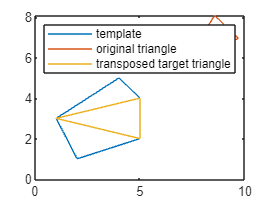



A1=[points(1,1)-xc -points(1,2)-yc 1 0; points(1,2)-yc  points(1,1)-xc 0 1;
   points(2,1)-xc -points(2,2)-yc 1 0; points(2,2)-yc  points(2,1)-xc 0 1;
   points(3,1)-xc -points(3,2)-yc 1 0; points(3,2)-yc  points(3,1)-xc 0 1;
   points(4,1)-xc -points(4,2)-yc 1 0; points(4,2)-yc  points(4,1)-xc 0 1;
   points(5,1)-xc -points(5,2)-yc 1 0; points(5,2)-yc  points(5,1)-xc 0 1];

R1 = A*Q;
cols=length(R1)/2;
R=reshape(R1,[2,cols]);
x1 = R(1,:);
y1 = R(2,:);
clf

x11 = points(:,1);
y11 = points(:,2);
plot([x11',points(1,1),],[y11',points(1,2),]) % template
hold on
plot([xt,xt(1)],[yt,yt(1)]); % original triangle
hold on

plot([x1,R(1,1)], [y1,R(2,1)]); % transposed target triangel

legend('template','original triangle','transposed target triangle')